# ALNC Lab Assignment-1 Question-1

clc;
clear;
close all;
figure;

## Simple pendulum system

% Parameters
g = 9.81; % Acceleration due to gravity [m/s^2]
l = 0.1; % Length of the pendulum [m]
m = 0.01; % Mass of the pendulum [kg]
b = 0.01; % Damping coefficient
t_end = 40; % Simulation time span [s]
h = 0.01;
tsamples = (0:h:t_end)';

% State initialisation
numSamples = length(tsamples);
X = zeros(2, numSamples);

% Initial state value
x0 = [pi / 6; pi / 12];
X(:, 1) = x0;

% State space representation
f = @(t, x) [x(2); (- (g / l) * sin(x(1)) - (b / (m * l * l)) * x(2))];

## Runge Kutta method | Order 4

% Implementation
tic
for i = 1:numSamples - 1
    k_1 = h * f(tsamples(i), X(:, i));
    k_2 = h * f(tsamples(i) + h / 2, X(:, i) + k_1 / 2);
    k_3 = h * f(tsamples(i) + h / 2, X(:, i) + k_2 / 2);
    k_4 = h * f(tsamples(i) + h, X(:, i) + k_3);
    X(:, i + 1) = X(:, i) + (1/6) * (k_1 + 2 * k_2 + 2 * k_3 + k_4);
end
toc

Elapsed time is 0.110663 seconds.


### Plots

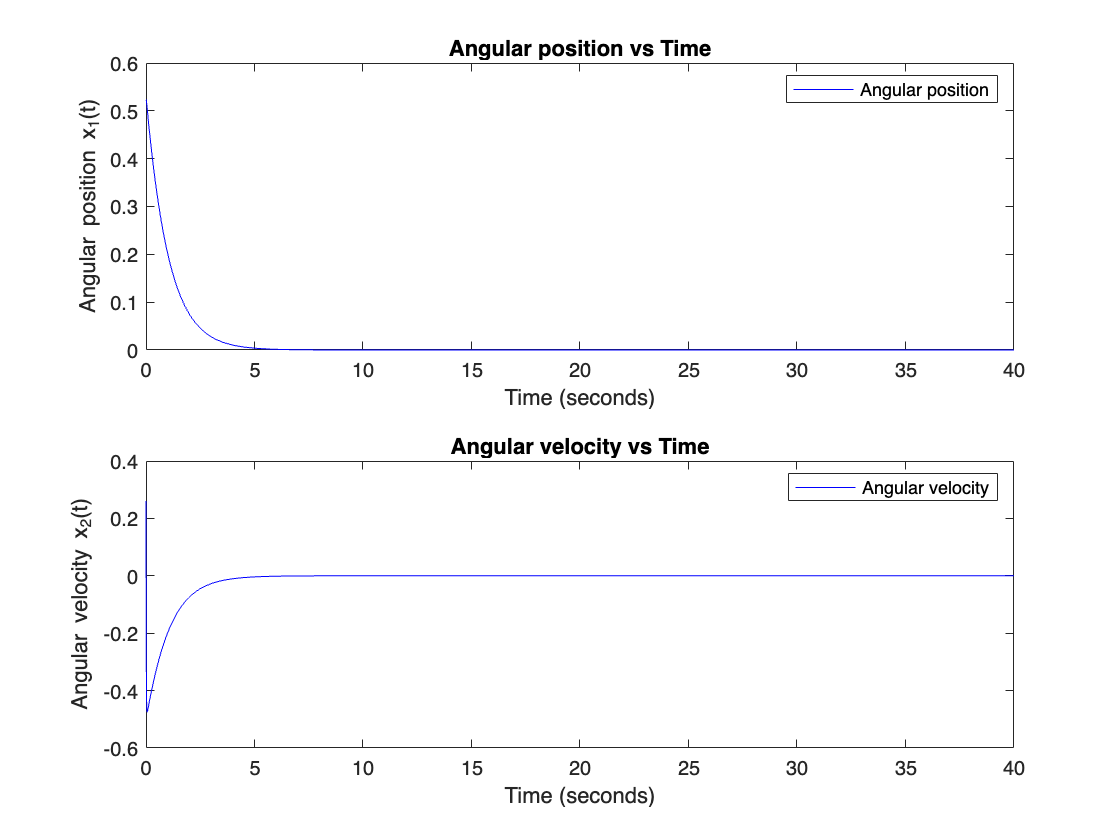

subplot(2, 1, 1);
plot(tsamples, X(1, :), "b", "DisplayName", "Angular position");
ylabel("Angular position x_1(t)");
xlabel("Time (seconds)");
title('Angular position vs Time');
legend();

subplot(2, 1, 2);
plot(tsamples, X(2, :), "b", "DisplayName", "Angular velocity");
ylabel("Angular velocity x_2(t)");
xlabel("Time (seconds)");
title('Angular velocity vs Time');
legend();

# `ALNC Lab Assignment-1 Question-2`

clc;
clear;
close all;
figure;

## `Permanent Magnet DC Motor (PMDC) system`

% Constants
R_a = 0.1; % [Ohm]
L_a = 0.01; % [H]
J = 10; % [kgm^2]
B = 0.01; % [Nms]
k_b = 1; % [Vs/rad]
k_t = 1; % [Nm/A]
tspan = 90; % Time span [s]
T_load = 0; % Load torque [Nm]
V_inp = 20; % Input voltage [V]
x0 = [0; 0]; % Initial state value

h = 0.01; % Step size
tsamples = (0:h:tspan)'; % Time samples
numSamples = length(tsamples);
X = zeros(2, numSamples);

% State space representation
f = @(t, x) [(1 / L_a) * (V_inp - R_a * x(1) - k_b * x(2)); ...
                 (1 / J) * (k_t * x(1) - B * x(2) - T_load)];

## `Euler's method`

% Implementation
tic

for i = 1:numSamples - 1
    X(:, i + 1) = X(:, i) + h * f(tsamples(i), X(:, i));
end

toc

Elapsed time is 0.047640 seconds.


### `Plots`

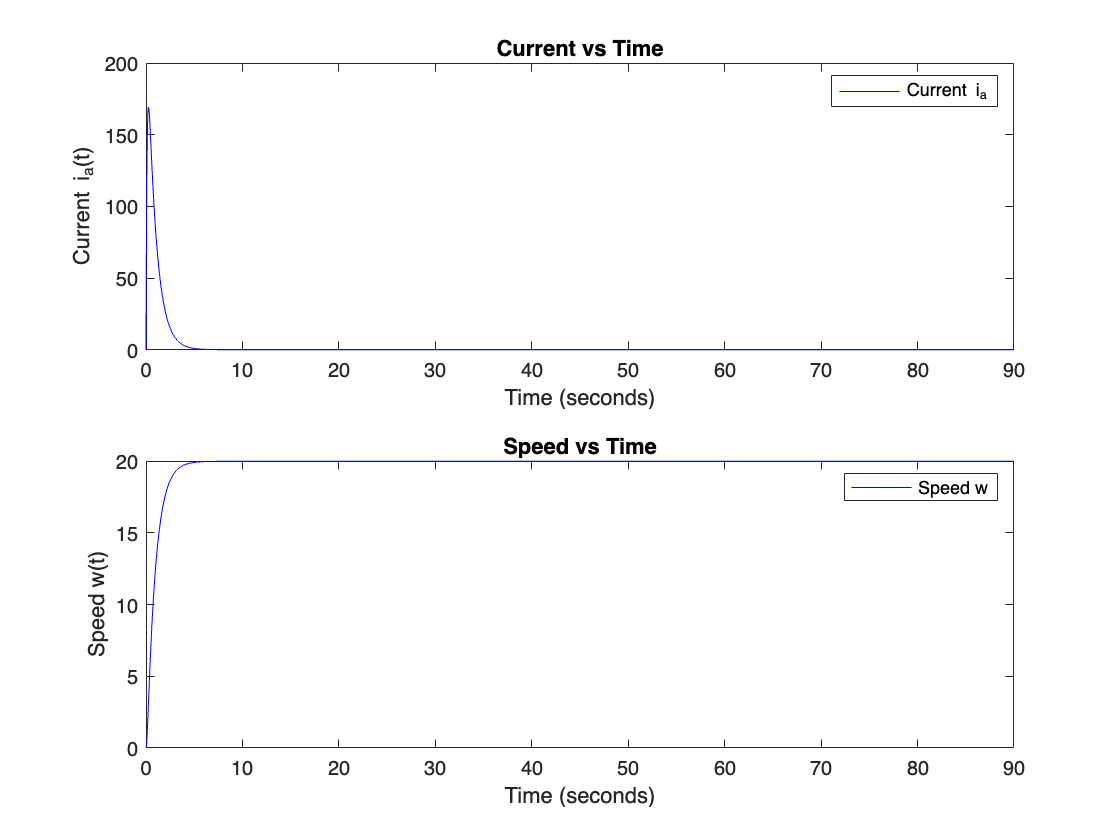

subplot(2, 1, 1);
plot(tsamples, X(1, :), "b", "DisplayName", "Current i_a");
ylabel("Current i_a(t)");
xlabel("Time (seconds)");
title('Current vs Time');
legend();

subplot(2, 1, 2);
plot(tsamples, X(2, :), "b", "DisplayName", "Speed w");
ylabel("Speed w(t)");
xlabel("Time (seconds)");
title('Speed vs Time');
legend();